% Data load & utils
load('test_kspace.mat');
addpath(genpath('utils'));
addpath(genpath('AC_LORAKS'));

## **Multi-Contrast Images from Fully Sampled Recon**

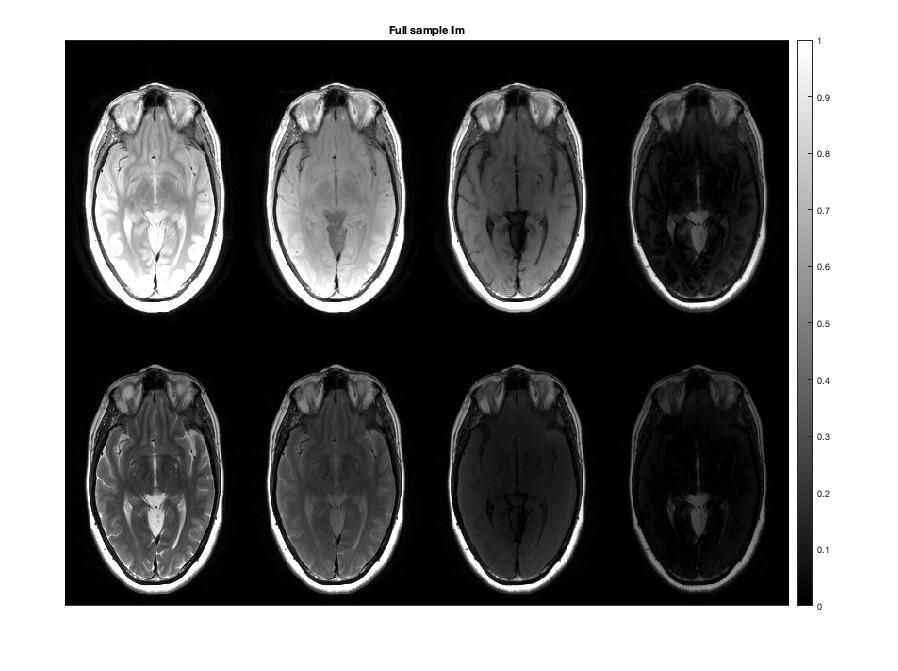

% Full sample
Img_Full = ifft2c(measc_cc_12z);
Full_comb_Im = squeeze(sum(Img_Full.*conj(Sens_12z),4));
figure; 

dpi = 500;            % Just for better dpi visulization
sz = [0 0 192*4 300*2]; % Image size in pixels

figure(...
  'PaperUnits','inches',...
  'PaperPosition', sz/dpi,...
  'PaperPositionMode','manual')

imshow3(abs(Full_comb_Im),[0 1],[2 4]);

title('Full sample Im');colorbar;axis off image; colormap gray;

## **Multi-Contrast Images from JVC GRAPPA Recon (R=6)**


% JVC_GRAPPA
clearvars -except measc_cc_12z Sens_12z dpi sz;
True_k = single(measc_cc_12z);

[feRes, peRes, zRes, cRes, dRes, eRes] = size(True_k);

R = 6; nacs = 20; kSize = [3, R+1];

% JVC_GRAPPA
lamda = 0.0001; pat = zeros(size(True_k));
pat(:,1:R:end,:,:,1,:) = 1;
pat(:,4:R:end,:,:,2,:) = 1;
pat(:,1:R:end,:,:,3,:) = 1;
pat(:,4:R:end,:,:,4,:) = 1;

JVC_GRAPPA_Recon = make_Recon_k(True_k, pat, nacs, kSize, lamda);

JVC_GRAPPA   0% --:--:--Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool JVC_GRAPPA Done. [199 seconds]


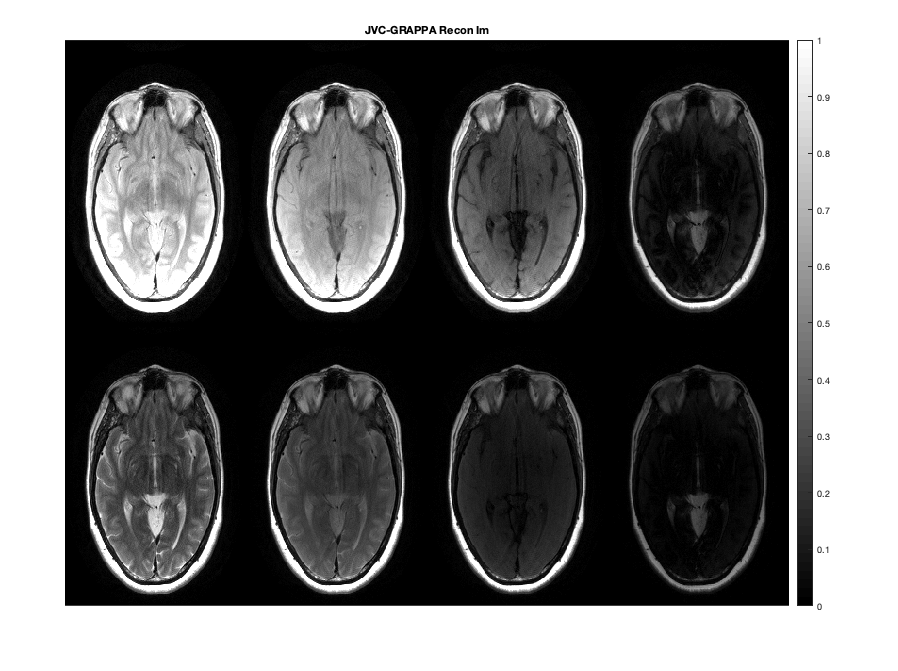

Img_JVC_GRAPPA_Recon = ifft2c(JVC_GRAPPA_Recon);
JVC_GRAPPA_comb_Im = squeeze(sum(Img_JVC_GRAPPA_Recon.*conj(Sens_12z),4));
figure(...
  'PaperUnits','inches',...
  'PaperPosition', sz/dpi,...
  'PaperPositionMode','manual');
imshow3(abs(JVC_GRAPPA_comb_Im),[0 1],[2 4]);title('JVC-GRAPPA Recon Im');colorbar;axis off image; colormap gray;

## **Multi-Contrast Images from JVC GRAPPA Recon **

**(R = 4 with partial Fourier 1/4, Note that same number of lines are used as  JVC-GRAPPA for R=6)**

**For this, you will need to download ACS-LORAKS Recon code from **[http://mr.usc.edu/download/LORAKS2/](http://mr.usc.edu/download/LORAKS2/)


% JLORAKS
clearvars -except measc_cc_12z Sens_12z dpi sz;

% Step 1. Data setting
Full_k = double(squeeze(measc_cc_12z(:,:,:,:,:,:)));
[ref_feRes, ref_peRes, ref_zRes, ref_cRes, ref_dRes, ref_eRes] = size(measc_cc_12z);
Full_k = reshape(Full_k,[ref_feRes, ref_peRes, ref_zRes, ref_cRes, ref_dRes*ref_eRes]);
[feRes, peRes, zRes, cRes, Cont] = size(Full_k);

num_acs = [feRes-2,20];

% ######### Setting sampling pattern ##################
p = 1/4;  R_fe = 1;  R_pe = 4;

partial = peRes*p;
partial_k = Full_k; partial_k(:,1:partial,:,:,:) = 0;

del_fe = ([0, 0, 0, 0]);
del_pe = ([partial-1+ 1,...
           partial-1+ 3,...
           partial-1+ 1,...
           partial-1+ 3]);
clear p partial;

% ######### Sampling mask ##################
[shift_fe, shift_pe] = Contrast_shift_util_jh(del_fe, del_pe, cRes); clear del_fe del_pe;
mask = JLORAKS_mask_util_jh(num_acs, feRes, peRes, zRes, cRes, Cont, R_fe, R_pe, shift_fe, shift_pe); clear shift_fe shift_pe;
tmp_mask = reshape(mask, feRes, peRes, zRes, []);

% ######### Left_partial + undersampled data ##################
tmp_partial_under_k = double(partial_k .* mask);
partial_under_k = reshape(tmp_partial_under_k, feRes, peRes, zRes, []); clear partial_k tmp_partial_under_k;

%% joint LORAKS
r_S = 500;      % rank constraint
neighbor_R = 2; % local k-space radius

pcg_tol = 1e-2; % pcg tolerance to terminate
pcg_iter = 50;  % pcg max iterations

% ######### JLORAKS ##################
JLORAKS_k = zeros(feRes, peRes, zRes, cRes*Cont);
for zz = 1:zRes
    tic
    disp(strcat('slice : ', num2str(zz)));
    JLORAKS_k(:,:,zz,:) = AC_LORAKS(squeeze(partial_under_k(:,:,zz,:)),...
        squeeze(tmp_mask(:,:,zz,:)),r_S,neighbor_R,'C',0,2,pcg_tol,pcg_iter,1);
    toc
end

slice :1


AC-LORAKS Reconstruction
pcg converged at iteration 22 to a solution with relative residual 0.0098.


Elapsed time is 221.175427 seconds.


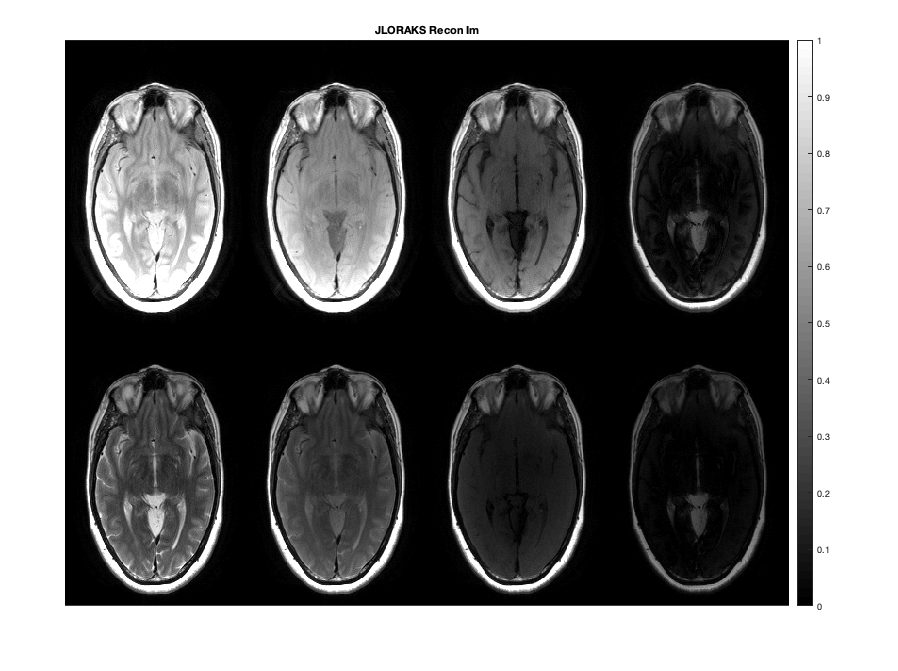


JLORAKS_k = reshape(JLORAKS_k(1:feRes*peRes*zRes*cRes*Cont), [feRes, peRes, zRes, cRes, Cont]);
JLORAKS_Recon = single(reshape(JLORAKS_k,[ref_feRes, ref_peRes, ref_zRes, ref_cRes, ref_dRes, ref_eRes]));

Img_JLORAKS_Recon = ifft2c(JLORAKS_Recon);
JLORAKS_comb_Im = squeeze(sum(Img_JLORAKS_Recon.*conj(Sens_12z),4));
figure(...
  'PaperUnits','inches',...
  'PaperPosition', sz/dpi,...
  'PaperPositionMode','manual');
imshow3(abs(JLORAKS_comb_Im),[0 1],[2 4]);
title('JLORAKS Recon Im');colorbar;axis off image; colormap gray;